% experiment1.mlx
% Bag of features, 400 words
% 520x514 px images
clc; clear; close all;
cd('~/Documents/jorgeMunoz/docMicrostructuresAI/experiments/conMatlab/experiment1b-diciembre2022/methods')

## Load image categories

%Imagenes 520x514 px

setDir = '/home/cima/Documents/jorgeMunoz/docMicrostructuresAI/materiales/microscopioMuestrasCIMA-EDIT/520x514_SIMETRICA'

setDir = '/home/cima/Documents/jorgeMunoz/docMicrostructuresAI/materiales/microscopioMuestrasCIMA-EDIT/520x514_SIMETRICA'

imds = imageDatastore(setDir,'IncludeSubfolders',true,'LabelSource',...
   'foldernames');
[trainingSet,testSet] = splitEachLabel(imds,0.7,'randomize');


## Bag of features

    %para Clasificacion

bag = bagOfFeatures(trainingSet, 'VocabularySize', 400, 'PointSelection', 'Detector' );

Creating Bag-Of-Features.
-------------------------
* Image category 1: annealing
* Image category 2: quenching
* Image category 3: quenchingtempered
* Selecting feature point locations using the Detector method.
* Extracting SURF features from the selected feature point locations.
** detectSURFFeatures is used to detect key points for feature extraction.

* Extracting features from 840 images...done. Extracted 1245131 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 1 has the least number of strongest features: 258770.
** Using the strongest 258770 features from each of the other image categories.

* Creating a 400 word visual vocabulary.
* Number of levels: 1
* Branching factor: 400
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 776310
* Number 

%para Test
bagTest = bagOfFeatures(testSet, 'VocabularySize', 400, 'PointSelection', 'Detector' );

Creating Bag-Of-Features.
-------------------------
* Image category 1: annealing
* Image category 2: quenching
* Image category 3: quenchingtempered
* Selecting feature point locations using the Detector method.
* Extracting SURF features from the selected feature point locations.
** detectSURFFeatures is used to detect key points for feature extraction.

* Extracting features from 360 images...done. Extracted 526657 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 1 has the least number of strongest features: 107606.
** Using the strongest 107606 features from each of the other image categories.

* Creating a 400 word visual vocabulary.
* Number of levels: 1
* Branching factor: 400
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 322818
* Number o

## Image Features

%TRAIN

imagefeatures = encode(bag, trainingSet);

Encoding images using Bag-Of-Features.
--------------------------------------
* Image category 1: annealing
* Image category 2: quenching
* Image category 3: quenchingtempered
* Encoding 840 images...done.


micrographData = array2table(imagefeatures)

micrographData = 840×400 table
    imagefeatures1    imagefeatures2    imagefeatures3    imagefeatures4    imagefeatures5    imagefeatures6    imagefeatures7    imagefeatures8    imagefeatures9    imagefeatures10    imagefeatures11    imagefeatures12    imagefeatures13    imagefeatures14    imagefeatures15    imagefeatures16    imagefeatures17    imagefeatures18    imagefeatures19    imagefeatures20    imagefeatures21    imagefeatures22    imagefeatures23    imagefeatures24    imagefeatures25    imagefeatures26    imagefeatures27    <s

micrographData.tipo = trainingSet.Labels

micrographData = 840×401 table
    imagefeatures1    imagefeatures2    imagefeatures3    imagefeatures4    imagefeatures5    imagefeatures6    imagefeatures7    imagefeatures8    imagefeatures9    imagefeatures10    imagefeatures11    imagefeatures12    imagefeatures13    imagefeatures14    imagefeatures15    imagefeatures16    imagefeatures17    imagefeatures18    imagefeatures19    imagefeatures20    imagefeatures21    imagefeatures22    imagefeatures23    imagefeatures24    imagefeatures25    imagefeatures26    imagefeatures27    <s

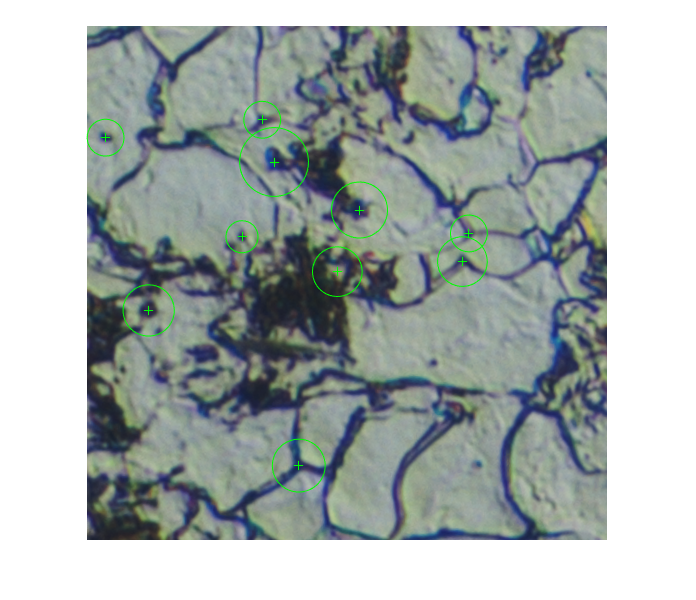

% "encode" counts the visual word occurrences in an image. 
% It produced a histogram that becomes a new and reduced 
% representation of an image
% Plot the histogram for 1 image
imgAnneal = readimage(trainingSet, 1);
points =  detectSURFFeatures(rgb2gray(imgAnneal));
imshow(imgAnneal);hold on;plot(points.selectStrongest(10));

%featureVector = imagefeatures(:, 1);
featureVectorAnneal = encode(bag, imgAnneal);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


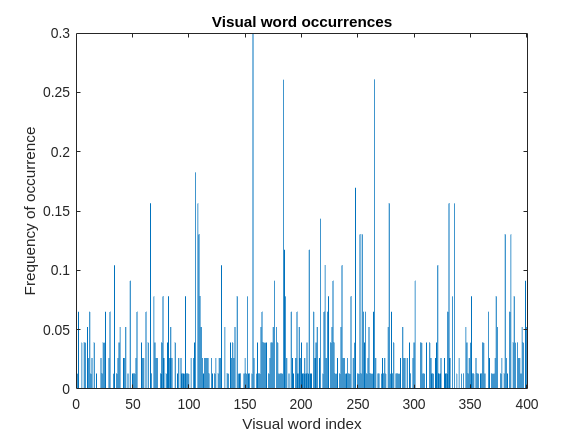

writematrix(featureVectorAnneal,'anneal.xlsx')


figure
bar(featureVectorAnneal);
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')

featureVectorAnnealSinOrdenar = featureVectorAnneal

featureVectorAnnealSinOrdenar = 1×400 single row vector
    0.0130    0.0652         0         0    0.0391         0    0.0391    0.0391         0    0.0522    0.0261    0.0652    0.0130    0.0261         0    0.0391         0    0.0130         0         0         0    0.0261    0.0130    0.0391    0.0391    0.0652         0         0    0.0261    0.0652         0         0    0.0130    0.1043         0    0.0130    0.0261    0.0391    0.0522         0         0    0.0261    0.0261    0.0522         0    0.0130         0    0.0913         0    0.0130


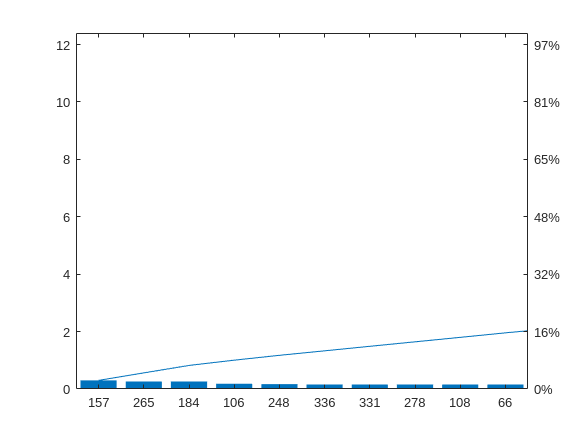

pareto(featureVectorAnnealSinOrdenar)

%ordenar de strongest a weakest
featureVectorAnneal = sort(featureVectorAnneal,"descend")

featureVectorAnneal = 1×400 single row vector
    0.2999    0.2608    0.2608    0.1826    0.1695    0.1565    0.1565    0.1565    0.1565    0.1565    0.1434    0.1304    0.1304    0.1304    0.1304    0.1304    0.1174    0.1174    0.1043    0.1043    0.1043    0.1043    0.1043    0.0913    0.0913    0.0913    0.0913    0.0913    0.0782    0.0782    0.0782    0.0782    0.0782    0.0782    0.0782    0.0782    0.0782    0.0782    0.0782    0.0782    0.0782    0.0782    0.0652    0.0652    0.0652    0.0652    0.0652    0.0652    0.0652    0.0652


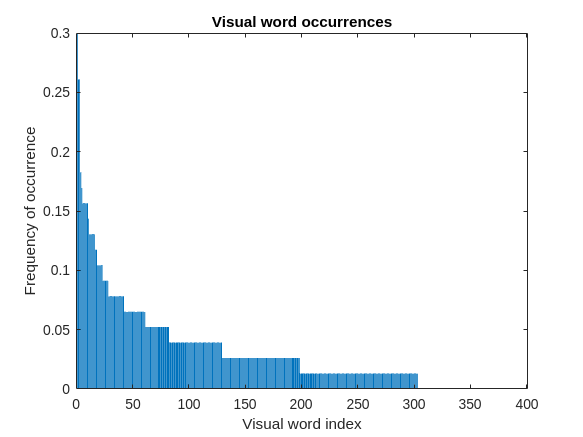

writematrix(featureVectorAnneal,'annealSorted.xlsx')
figure
bar(featureVectorAnneal);
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')

nZerosAnneal = numel(featureVectorAnneal) - nnz(featureVectorAnneal)

nZerosAnneal = 97

% Plot the histogram for 1 image
imgQuench = readimage(trainingSet, 373);
points =  detectSURFFeatures(rgb2gray(imgQuench));

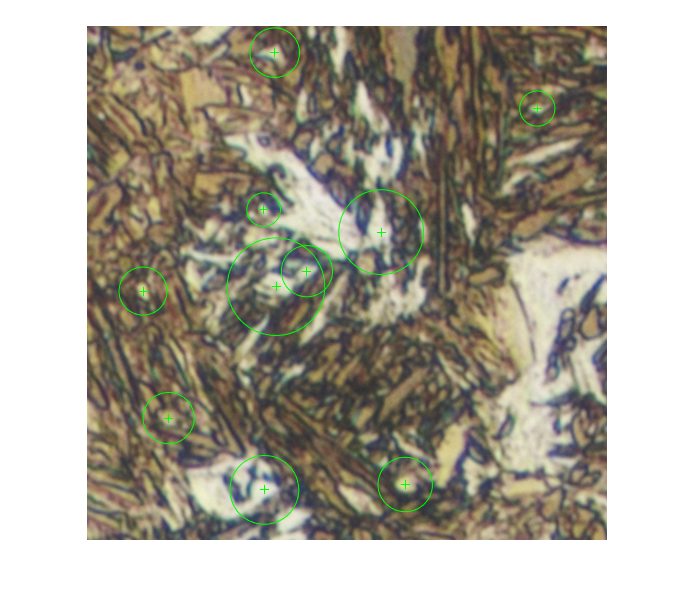

imshow(imgQuench);hold on;plot(points.selectStrongest(10));

featureVectorQuench = encode(bag, imgQuench);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


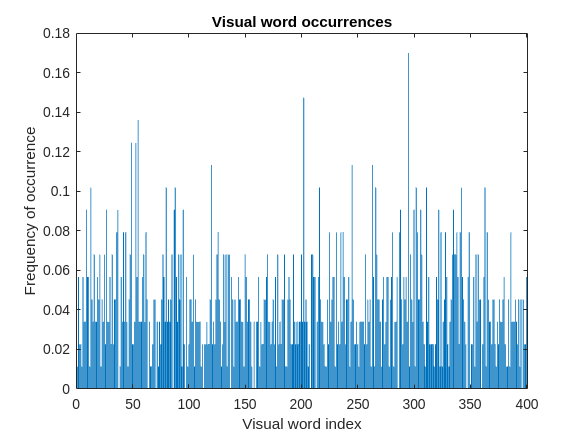

writematrix(featureVectorQuench,'quenched.xlsx')
figure
bar(featureVectorQuench)
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')

featureVectorQuench = sort(featureVectorQuench, "descend")

featureVectorQuench = 1×400 single row vector
    0.1699    0.1472    0.1359    0.1246    0.1246    0.1132    0.1132    0.1132    0.1019    0.1019    0.1019    0.1019    0.1019    0.1019    0.1019    0.1019    0.1019    0.0906    0.0906    0.0906    0.0906    0.0906    0.0906    0.0906    0.0906    0.0906    0.0906    0.0793    0.0793    0.0793    0.0793    0.0793    0.0793    0.0793    0.0793    0.0793    0.0793    0.0793    0.0793    0.0793    0.0793    0.0793    0.0793    0.0793    0.0793    0.0793    0.0679    0.0679    0.0679    0.0679


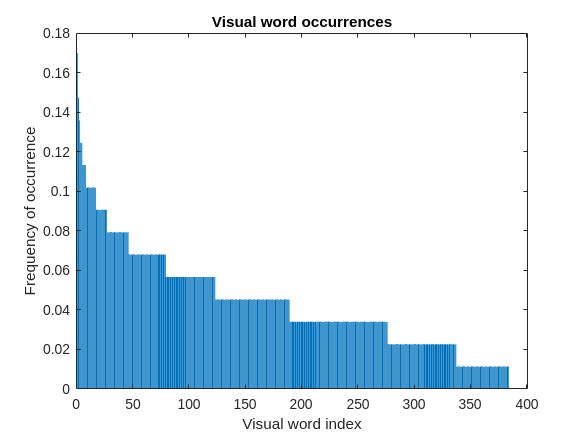

writematrix(featureVectorQuench,'quenchedSorted.xlsx')
figure
bar(featureVectorQuench)
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')

nZerosQuench = numel(featureVectorQuench) - nnz(featureVectorQuench)

nZerosQuench = 16

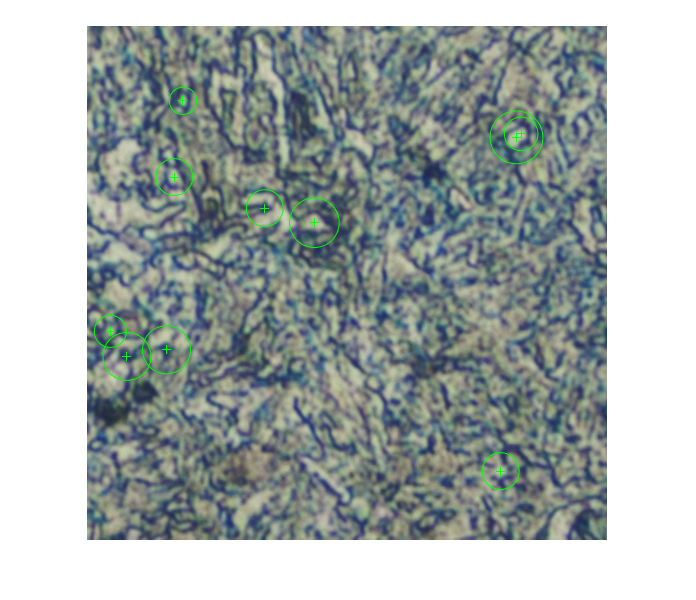

% Plot the histogram for 1 image
imgQuenchTemp = readimage(trainingSet, 840);
points =  detectSURFFeatures(rgb2gray(imgQuenchTemp));
imshow(imgQuenchTemp);hold on;plot(points.selectStrongest(10));

featureVectorQuenchTemp = encode(bag, imgQuenchTemp);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


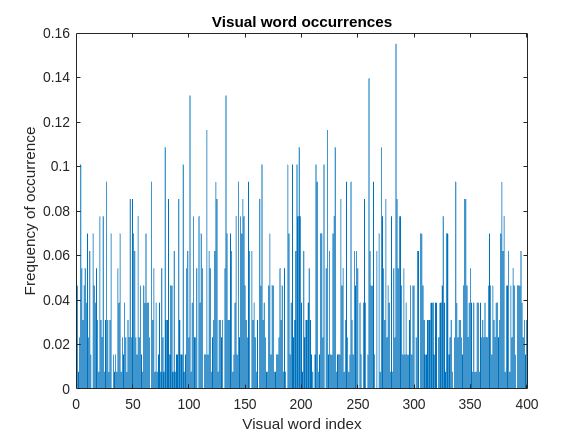

writematrix(featureVectorQuenchTemp,'quenchTempered.xlsx')
figure
bar(featureVectorQuenchTemp)
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')


figure
featureVectorQuenchTemp = sort(featureVectorQuenchTemp, "descend")

featureVectorQuenchTemp = 1×400 single row vector
    0.1552    0.1397    0.1319    0.1319    0.1164    0.1164    0.1086    0.1086    0.1086    0.1086    0.1009    0.1009    0.1009    0.1009    0.1009    0.1009    0.1009    0.1009    0.0931    0.0931    0.0931    0.0931    0.0931    0.0931    0.0931    0.0931    0.0931    0.0931    0.0931    0.0854    0.0854    0.0854    0.0854    0.0854    0.0854    0.0854    0.0854    0.0854    0.0854    0.0854    0.0854    0.0854    0.0776    0.0776    0.0776    0.0776    0.0776    0.0776    0.0776    0.0776


writematrix(featureVectorQuenchTemp,'quenchTemperedSorted.xlsx')
bar(featureVectorQuench)
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')

nZerosQuenchTemp = numel(featureVectorQuenchTemp) - nnz(featureVectorQuenchTemp)

nZerosQuenchTemp = 21


%TEST

imagefeaturesTest = encode(bagTest, testSet);

Encoding images using Bag-Of-Features.
--------------------------------------
* Image category 1: annealing
* Image category 2: quenching
* Image category 3: quenchingtempered
* Encoding 360 images...done.


micrographDataTest = array2table(imagefeaturesTest)

micrographDataTest = 360×400 table
    imagefeaturesTest1    imagefeaturesTest2    imagefeaturesTest3    imagefeaturesTest4    imagefeaturesTest5    imagefeaturesTest6    imagefeaturesTest7    imagefeaturesTest8    imagefeaturesTest9    imagefeaturesTest10    imagefeaturesTest11    imagefeaturesTest12    imagefeaturesTest13    imagefeaturesTest14    imagefeaturesTest15    imagefeaturesTest16    imagefeaturesTest17    imagefeaturesTest18    imagefeaturesTest19    imagefeaturesTest20    imagefeaturesTest21    imagefeaturesTest22    imagefeaturesTest23    imagefeaturesTest24    im

micrographDataTest.tipo = testSet.Labels

micrographDataTest = 360×401 table
    imagefeaturesTest1    imagefeaturesTest2    imagefeaturesTest3    imagefeaturesTest4    imagefeaturesTest5    imagefeaturesTest6    imagefeaturesTest7    imagefeaturesTest8    imagefeaturesTest9    imagefeaturesTest10    imagefeaturesTest11    imagefeaturesTest12    imagefeaturesTest13    imagefeaturesTest14    imagefeaturesTest15    imagefeaturesTest16    imagefeaturesTest17    imagefeaturesTest18    imagefeaturesTest19    imagefeaturesTest20    imagefeaturesTest21    imagefeaturesTest22    imagefeaturesTest23    imagefeaturesTest24    im

## Train Model

% Train model 
%The function trains a support vector machine (SVM) multiclass classifier using the input bag
%categoryClassifier = trainImageCategoryClassifier(trainingSet,bag);



## Evaluate Model

%TRAIN

%confMatrix = evaluate(categoryClassifier, trainingSet);
%[confMat,knownLabelIdx,predictedLabelIdx,score] = evaluate(categoryClassifier,trainingSet) 

%TEST

%confMatrixTest = evaluate(categoryClassifier,testSet)
%[confMat,knownLabelIdx,predictedLabelIdx,score] = evaluate(categoryClassifier,testSet) 


%trainMean = mean(diag(confMatrix))
%testMean = mean(diag(confMatrixTest))

save('experiment1b.mat')


## Predict single image


% I = imread("image.jpg");
%[labelIdx,score] = predict(categoryClassifier,I);